# Semi-autocalibration of a cellphone camera

Given an image taken from a camera, we use calibration tecniques to extract intrinsic and extrinsic parameters. 

In this script, we *iteratively* calibrate a cellphone camera using 1 of the 4 images taken, slowly minimizing the errors.

Read the image and the pre-decided 3D points that will form the M matrix; then prepare the file output path.

imgs_folder = '../0.calib_imgs';
img_subject = 'cube';
img_filename = 'img_3';

% load the calibration image
img_folder = fullfile(imgs_folder, img_subject);
img_file = strcat(img_filename, '.jpg');
img_path = fullfile(img_folder, img_file);
calib_img = imread(img_path);

% load 3D points
calib_points_path = fullfile(img_folder, '3D-points.mat');
load(calib_points_path, 'calib_points');

% prepare result
calib_result_folder = '../0.calib_results';
[~,~,~] = mkdir(calib_result_folder);
calib_result_file = sprintf('autocalib-%s-%s.mat', img_subject, img_filename);
calib_result_path = fullfile(calib_result_folder, calib_result_file);

clear imgs_folder img_subject img_filename img_folder img_file img_path ...
    calib_result_folder calib_result_file calib_points_path;

Ask the user the associated 2D points in the image (in total we'll have $n$ 3D points in the $M$ matrix mapped to $n$ 2D points in the $m$ matrix). The 3D points are stored as a 4-by-$n$ matrix and the 2D points are stored as a 3-by-$n$ matrix: this choice is due to the fact that in perspective space coordinates are handy if homogeneous, thus 3D points need 4 parameters and 2D points need 3.

% 3D points, in meters
M = calib_points;
n = size(M, 2);

% 2D points
m = zeros(3, n);

% ask the user n image points
figure('Name','Select image points');
set(gcf,'Visible','on'); % so live script will show an external figure

imshow(calib_img), hold on;

handles.scatter_m = {};
for i=1:n
    [u, v] = ginput(1);
    m(:,i) = [u; v; 1];
    handles.scatter_m = [handles.scatter_m, scatter(m(1,i), m(2,i), '+r')];
    drawnow;
end
% reproject everything as one handle
delete(handles.scatter_m);
handles.scatter_m = scatter(m(1,:), m(2,:), '+r');

clear u v b i calib_points;
close(gcf);

Iteratively refine the calibration.

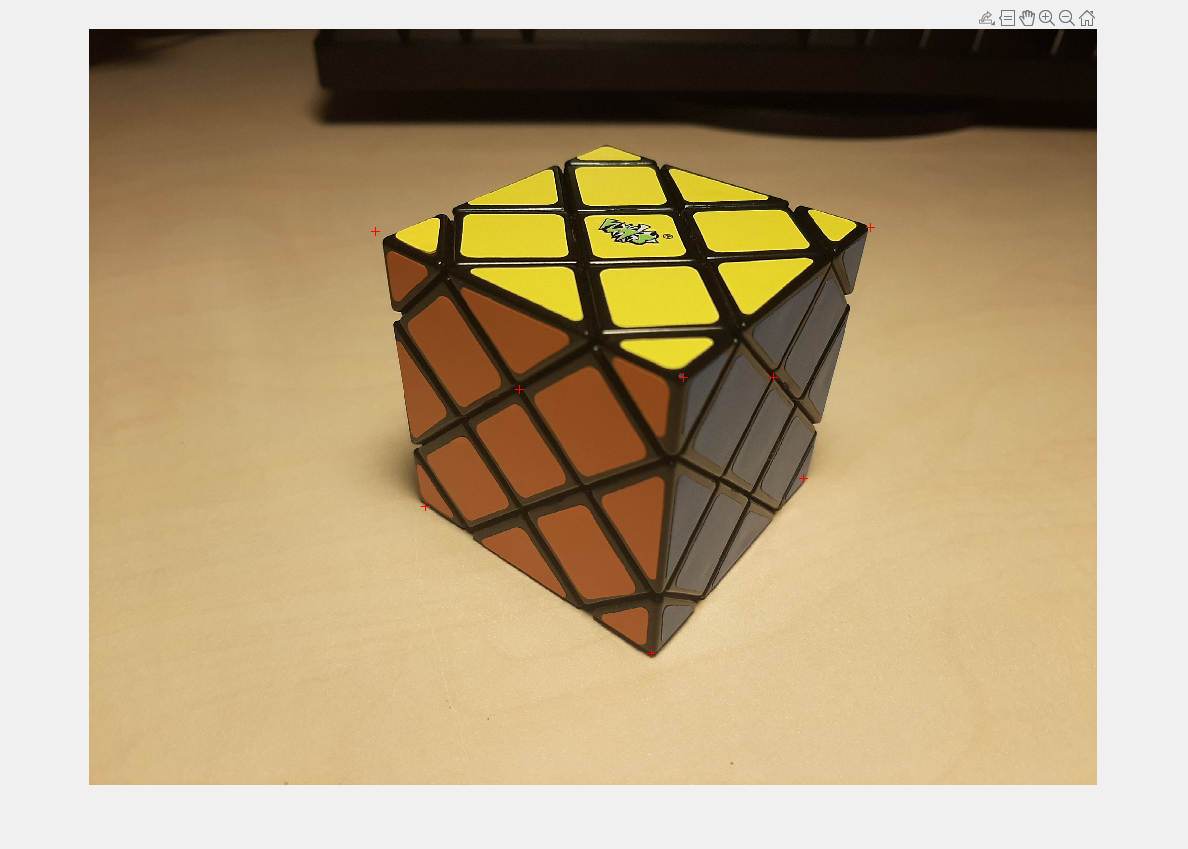

n_iterations = 10;

figure('Name','Refining...');
set(gcf,'Visible','on'); % so live script will show an external figure
imshow(calib_img), hold on;

for i=1:n_iterations
    cal = dlt(m, M);
    
    % reproject the calibration points with the current P matrix
    m_reproj = project(cal.P, M);
    handles.scatter_m_reproj = scatter(m_reproj(1,:), m_reproj(2,:), 'ob');
    
    % refine m
    m = (m + m_reproj)./2;
    
    % reproject the calibration points with the current P matrix
    pause(0.10);
    delete(handles.scatter_m); % clears the scatter of the points
    handles.scatter_m = scatter(m(1,:), m(2,:), '+r');
    delete(handles.scatter_m_reproj); % clears the scatter of the reprojections
end

set(gcf,'Name',sprintf('Final calibration after %d iterations', n_iterations));

clear i m_reproj n_iterations handles;

Save final results.

cal = dlt(m, M);
cal.image = calib_img;
save(calib_result_path, '-struct', 'cal');

clear calib_img m M n calib_results_path;